T = importdata('TempMed.mat');
n = length(T(:,1));
x = 0:0.05:1;
t = 0:60;

 

#### Evolucion de la temperatura a lo largo de la barra de acero en el tiempo

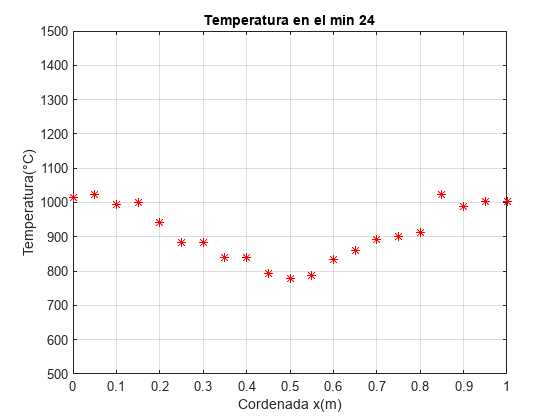

for i = 1:n
    plot(x,T(i,:),'r*')
    title(sprintf('Temperatura en el min %d',i-1))
    xlabel('Cordenada x(m)')
    ylabel('Temperatura(°C)')
    grid on
    ylim([500 1500])
    pause(1 -0.6)
end

clf
for i = 1:n
    TemperaturaPromedio = promedio(T(i,:));
    hold on
    plot(i,TemperaturaPromedio,'bo')
    hold off
end
surf(T)

## Ajuste discreto

Se propone la funcion de ajuste: $T\left(x,t\right)=c_1 +400\cos \left(c_2 x\right)e^{-\lambda 4\pi 2t} +100\cos \left(\frac{4\pi *x}{L}\right)e^{-c_3 t} \;\left\lbrack \textrm{◦C}\right\rbrack$ que predice la temperatura a lo largo de la barra para cada instante de tiempo, pero de desconocen las constantes $c_1 ,c_2 \;y\;c_3$

Se buscaran valores para $$c_1 ,c_2 \;y\;c_3$$ que minimicen el error cuadratico medio (ECM)


$$\textrm{ECM}=\frac{\sum_{i\;=\;1}^{61} \sum_{j\;=\;1}^{21} {\left\lbrack {\mathbf{T}}_{i,j} -\mathbf{T}\left(x_j ,t_i ,c_1 ,c_2 ,c_3 \right)\right\rbrack }^2 }{61*21}$$


Los $$c_1 ,c_2 \;y\;c_3$$ que minimicen el ECM, seran los que satisfagan el siguiente sistema de ecuaciones


$$f_1 \;=\;\frac{\partial }{\partial c_1 }\textrm{ECM}\;=\;\frac{\sum_{i\;=\;1}^{61} \sum_{j\;=\;1}^{21} -2*{\left\lbrack {\mathbf{T}}_{i,j} -c_1 -400\cos \left(c_2 x_j \right)*e^{-\lambda 4\pi^2 t_i } -100\cos \left(\frac{4\pi {*x}_j }{L}\right)*e^{-c_3 t_i } \right\rbrack } }{1281}=0$$



$$f_2 \;=\;\frac{\partial }{\partial c_2 }\textrm{ECM}\;=\;\frac{\sum_{i\;=\;1}^{61} \sum_{j\;=\;1}^{21} 800x_j *\textrm{sen}\left(c_2 x_j \right)*e^{-\lambda 4\pi^2 t_i } \left\lbrack {\mathbf{T}}_{i,j} -c_1 -400\cos \left(c_2 x_j \right)*e^{-\lambda 4\pi^2 t_i } -100\cos \left(\frac{4\pi *x_j }{L}\right)*e^{-c_3 t_i } \right\rbrack }{1281}=0$$



$$f_3 \;=\;\frac{\partial }{\partial c_3 }\textrm{ECM}\;=\;\frac{\sum_{i\;=\;1}^{61} \sum_{j\;=\;1}^{21} 200c_3 \cos \left(\frac{4\pi *x_j }{L}\right)*e^{-c_3 t_i } \left\lbrack {\mathbf{T}}_{i,j} -c_1 -400\cos \left(c_2 x_j \right)*e^{-\lambda 4\pi^2 t_i } -100\cos \left(\frac{4\pi *x_j }{L}\right)*e^{-c_3 t_i } \right\rbrack }{1281}=0$$


Este sistema de ecuaciones no lineales se puede resolver mediante el metodo de Newton Raphson para sistemas de ecuaciones de la siguiente manera:


$$\left\lbrack \begin{array}{c}
c_1 \\
c_2 \\
c_3 
\end{array}\right\rbrack \approx \left\lbrack \begin{array}{c}
c_{1k} \\
c_{2k} \\
c_{3k} 
\end{array}\right\rbrack -\Delta C$$



$$\;\Delta C=\;\left\lbrack \begin{array}{ccc}
\frac{\partial }{\partial c_1 }f_1  & \frac{\partial }{\partial c_2 }f_1  & \frac{\partial }{\partial c_3 }f_1 \\
\frac{\partial }{\partial c_1 }f_2  & \frac{\partial }{\partial c_2 }f_3  & \frac{\partial }{\partial c_3 }f_3 \\
\frac{\partial }{\partial c_1 }f_3  & \frac{\partial }{\partial c_3 }f_3  & \frac{\partial }{\partial c_3 }f_3 
\end{array}\right\rbrack *\left\lbrack \begin{array}{c}
f_1 \left(c_1 ,c_2 ,c_3 \right)\\
f_2 \left(c_1 ,c_2 ,c_3 \right)\\
f_3 \left(c_1 ,c_2 ,c_3 \right)
\end{array}\right\rbrack$$


L = 1;
alfa = 22.8*10^(-6);
lamda = alfa/L^2;

J = zeros(3); % inicialización de la matriz de jacobianos
F = zeros(3,1); % inicialización del vector de funciones

La forma de calcular una derivada parcial numericamente es:


$$\frac{\partial }{\partial x_j }f_i \approx \frac{f_i \left(x_1 ,\ldotp \ldotp \ldotp ,x_j +\sigma x_j ,\ldotp \ldotp \ldotp ,x_n \right)-f_i \left(x_1 ,\ldotp \ldotp \ldotp ,x_j ,\ldotp \ldotp \ldotp ,x_n \right)}{\sigma x_j }$$


donde $\sigma x_j$ es un valor pequeño elegido arbitrariamente

% Este bloque evalua las funciones en todos sus terminos
dc1 = 0.1;
dc2 = 0.1;
dc3 = 0.1;
Contador = 0;
c1 = 100;
c2 = 3.14;
c3 = 2;

Tol = 0.01; Nmax = 10;
%while any(F >= Tol) && Contador < NMax
for k = 1:3
    for i = 1:61
        for j = 1:21

            % Terminos generales de las sumatorias (con el 1/1281 dentro)
            f1 = @(c1,c2,c3) ((-2*(T(i,j) - c1 - 400*cos(c2*x(j))*exp(-lamda*pi^2*4*t(i)) - 100*cos(4*pi*x(j)/L)*exp(-c3*t(i))))/1281);
            f2 = @(c1,c2,c3) (800*x(j).*exp(-lamda*pi^2*4*t(i))*sin(c2*x(j))*(T(i,j) - c1 - 400*cos(c2*x(j))*exp(-lamda*pi^2*4*t(i)) - 100*cos(4*pi*x(j)/L)*exp(-c3*t(i))))/1281;
            f3 = @(c1,c2,c3) (200*c3*cos(4*pi/L*x(j))*exp(-lamda*pi^2*4*t(i))*(T(i,j) - c1 - 400*cos(c2*x(j))*exp(-lamda*pi^2*4*t(i)) - 100*cos(4*pi*x(j)/L)*exp(-c3*t(i))))/1281;

            %%%%%%%%%%%%%%%% Matriz de jacobianos %%%%%%%%%%%%%%%%%%
            J(1,1) = J(1,1) + (f1(c1 + dc1,c2,c3)-f1(c1,c2,c3))/dc1;
            J(1,2) = J(1,2) + (f1(c1,c2 + dc2,c3)-f1(c1,c2,c3))/dc2;
            J(1,3) = J(1,3) + (f1(c1,c2,c3 + dc3)-f1(c1,c2,c3))/dc3;
            J(2,1) = J(2,1) + (f2(c1 + dc1,c2,c3)-f2(c1,c2,c3))/dc1;
            J(2,2) = J(2,2) + (f2(c1,c2 + dc2,c3)-f2(c1,c2,c3))/dc2;
            J(2,3) = J(2,3) + (f2(c1,c2,c3 + dc3)-f2(c1,c2,c3))/dc3;
            J(3,1) = J(3,1) + (f3(c1 + dc1,c2,c3)-f3(c1,c2,c3))/dc1;
            J(3,2) = J(3,2) + (f3(c1,c2 + dc2,c3)-f3(c1,c2,c3))/dc2;
            J(3,3) = J(3,3) + (f3(c1,c2,c3 + dc3)-f3(c1,c2,c3))/dc3;
            %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    
            %%%% Vector de funciones %%%%
            F(1) = F(1) + f1(c1,c2,c3);
            F(2) = F(2) + f2(c1,c2,c3);
            F(3) = F(3) + f3(c1,c2,c3);
    
        end
    end  

    dC = J^1 * F;
    c1 = c1 - dC(1);
    c2 = c2 - dC(2);
    c3 = c3 - dC(3);
    Contador = Contador + 1;
end
c1;c2;c3

c3 = NaN

Contador

Contador = 3